# Reserve Variance Live Script 5

## Change Folder

cd("F:\OneDrive - Queensland University of Technology\Research Assistant " ...
    + "Work (OD)\Dispersal Variability (OD)\Code")

cd("C:\Users\sowen\OneDrive - Queensland University of Technology\" + ...
    "Research Assistant Work (OD)\Dispersal Variability (OD)\Code")

## Load Data

if ~exist("workspaceVarReserveVariance", 'var')
    if feature("numcores") == 12
        maxNumCompThreads(12);
    else
        maxNumCompThreads(16);
    end
    load matlabReserveVariance.mat
    setInterpLatex()
end

## Save Data

 if exist("workspaceVarReserveVariance", 'var')
     eval(clearVars());
     save matlabReserveVariance.mat
 end

% set the default intepreter to latex
setInterpLatex()

## Contents

Re-doing Figures for Paper

Analytical System Figure Redo

Recalculating the Tables of Results

## Assumptions / Notes

## Re-loading COTS Matrices

% fml, need to re-load and redo some of this shit epicmode I love wasting
% time

% let's do the gbr1 matrices first
var1 = dir("../Data/Matrices 27-02-2024/GBR1_oceanParcel/GBR1*");
conMatsGBR1 = cell(1, 12);
gbr1Names = strings(size(conMatsGBR1));
for i = 1:12
    load("../Data/Matrices 27-02-2024/GBR1_oceanParcel/" + var1(i).name, ...
        "connectivityMatrixNormed");
    conMatsGBR1{i} = sparse(connectivityMatrixNormed);
    var2 = split(var1(i).name, "_");
    var2 = split(var2{end}, ".");
    gbr1Names(i) = strrep(var2{1}, "-", "");

    % double check there are no issues
    if max(max(connectivityMatrixNormed)) > 1
        "piss"
    end
    if max(sum(connectivityMatrixNormed, 2)) > 1
        "shit"
    end
    if min(min(connectivityMatrixNormed)) < 0
        "fuck"
    end
    clear connectivityMatrixNormed
end

% let's now load in the gbrl up matrices
var1 = dir("../Data/Matrices 27-02-2024/GBRL/*up*");
conMatsGBRLUp = cell(1, 30);
gbrlNames = strings(size(conMatsGBRLUp));
for i = 1:30
    load("../Data/Matrices 27-02-2024/GBRL/" + var1(i).name, ...
        "connectivityMatrixNormed");
    conMatsGBRLUp{i} = sparse(connectivityMatrixNormed);
    var2 = split(var1(i).name, "_");
    gbrlNames(i) = var2{3};

    % double check there are no issues
    if max(max(connectivityMatrixNormed)) > 1
        "piss"
    end
    if max(sum(connectivityMatrixNormed, 2)) > 1
        "shit"
    end
    if min(min(connectivityMatrixNormed)) < 0
        "fuck"
    end
    clear connectivityMatrixNormed
end

% let's now load in the gbrl dp matrices
var1 = dir("../Data/Matrices 27-02-2024/GBRL/*dp*");
conMatsGBRLDp = cell(1, 30);
gbrlNames = strings(size(conMatsGBRLDp));
for i = 1:30
    load("../Data/Matrices 27-02-2024/GBRL/" + var1(i).name, ...
        "connectivityMatrixNormed");
    conMatsGBRLDp{i} = sparse(connectivityMatrixNormed);
    var2 = split(var1(i).name, "_");
    gbrlNames(i) = var2{3};

    % double check there are no issues
    if max(max(connectivityMatrixNormed)) > 1
        "piss"
    end
    if max(sum(connectivityMatrixNormed, 2)) > 1
        "shit"
    end
    if min(min(connectivityMatrixNormed)) < 0
        "fuck"
    end
    clear connectivityMatrixNormed
end

% now load in the slim matrices
var1 = dir("../Data/Matrices 27-02-2024/SLIM/SLIM*");
conMatsSLIM = cell(1, 30);
SLIMNames = strings(size(conMatsSLIM));
for i = 1:30
    load("../Data/Matrices 27-02-2024/SLIM/" + var1(i).name, ...
        "connectivityMatrixNormed");
    conMatsSLIM{i} = sparse(connectivityMatrixNormed);
    var2 = split(var1(i).name, "_");
    SLIMNames(i) = var2{3};

    % double check there are no issues
    if max(max(connectivityMatrixNormed)) > 1
        "piss"
    end
    if max(sum(connectivityMatrixNormed, 2)) > 1
        "shit"
    end
    if min(min(connectivityMatrixNormed)) < 0
        "fuck"
    end
    clear connectivityMatrixNormed
end

## Re-doing Figures for Paper

% need to redo a bunch of the figures for the paper, first off going to do
% the one for the correlations

% calculate the correlations across the entire reef system and for each of
% the study areas
corrMatCT = calcLarvalCorr(conMatsCT);
corrMatCape = calcLarvalCorr(areaStructCape.conMats);
corrMatNorth = calcLarvalCorr(areaStructNorth.conMats);
corrMatCairns = calcLarvalCorr(areaStructCairns.conMats);
corrMatTowns = calcLarvalCorr(areaStructTowns.conMats);
corrMatSwains = calcLarvalCorr(areaStructSwains.conMats);

% do a nice big figure of them :)
figure
plotConnectivityStats({corrMatCT(:), corrMatCape(:), corrMatNorth(:), ...
    corrMatCairns(:), corrMatTowns(:), corrMatSwains(:)}, "correlationLoc", ...
    ["Whole GBR", "Cape Region", "Northern GBR Region", "Cairns Region", ...
    "Townsville Region", "Swains Region"]);
setFontSize(14)
figResize(1.3, 1.2)
lightFig()
saveFig("connectivityCorrLoc")
darkFig()
saveFig("connectivityCorrLocDM")

clear corrMatCT corrMatCape corrMatCairns corrMatTowns corrMatSwains

% gonna plot correlations based on time series of the row sums for each
% reef heheheeeehe, beginning with the coral trout data
corrMatCT = calcLarvalCorr(conMatsCT);
corrMatHawaii = calcLarvalCorr(conMatsHawaii);
corrMatSLIM = calcLarvalCorr(conMatsSLIM);
corrMatGBR1 = calcLarvalCorr(conMatsGBR1);
corrMatGBRLUp = calcLarvalCorr(conMatsGBRLUp);
corrMatGBRLDp = calcLarvalCorr(conMatsGBRLDp);

% do a nice big figure of them :)
conAnalysisColNames2 = conAnalysisColNames;
conAnalysisColNames2(5) = conAnalysisColNames2(4);
conAnalysisColNames2(4) = "COTS (GBR1)";

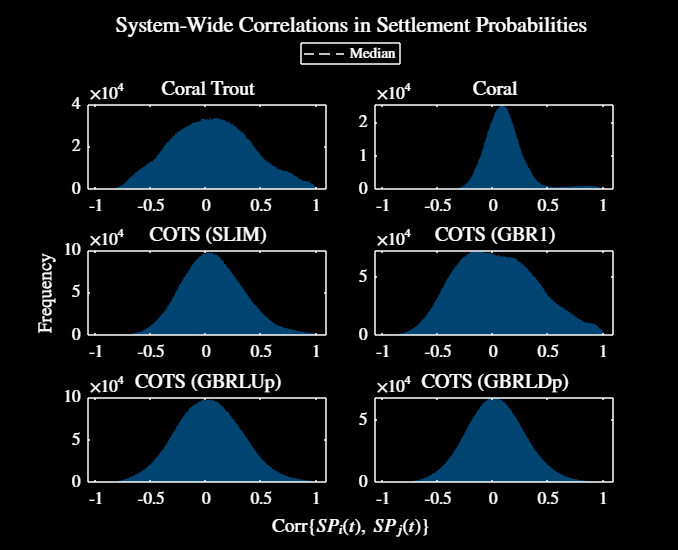

figure
plotConnectivityStats({corrMatCT(:), corrMatHawaii(:), corrMatSLIM(:), ...
    corrMatGBR1(:), corrMatGBRLUp(:), corrMatGBRLDp(:)}, "correlation", ...
    conAnalysisColNames2);
setFontSize(14)
figResize(1.3, 1.2)
lightFig()
saveFig("connectivityCorr")
darkFig()
saveFig("connectivityCorrDM")

clear corrMatCT corrMatHawaii corrMatSLIM corrMatGBRLUp corrMatGBR1 ...
    corrMatGBRLDp

% let's look at the autocorrelations figure here

% calculate the autocorrelations for the coral trout data
ind = [1:5, 7:11, 13:17, 19:23, 25:29];
[autocorrMonthlyCT, ~] = calcAutocorr(conMatsCT, eps, ind); 

% calculate the autocorrelations for the hawaii data
ind = [];
for i = 1:length(conMatsHawaii)
    if mod(i, 3) ~= 0
        ind = [ind, i];
    end
end
[autocorrMonthlyHawaii, ~] = calcAutocorr(conMatsHawaii, eps, ind);

% calculate the autocorrelations for the SLIM data
ind = [1:9, 11:19, 21:29];
[autocorrWeeklySLIM, ~] = calcAutocorr(conMatsSLIM, eps, ind);

% calculate the autocorrelations for the GB1 data
ind = [1:3, 5:7, 9:11];
[autocorrWeeklyGBR1, ~] = calcAutocorr(conMatsGBR1, eps, ind);

% calculate the autocorrelations for the GBRLUp data
ind = [1:9, 11:19, 21:29];
[autocorrWeeklyGBRLUp, ~] = calcAutocorr(conMatsGBRLUp, eps, ind);

% calculate the autocorrelations for the GBRLDp data
ind = [1:9, 11:19, 21:29];
[autocorrWeeklyGBRLDp, ~] = calcAutocorr(conMatsGBRLDp, eps, ind);

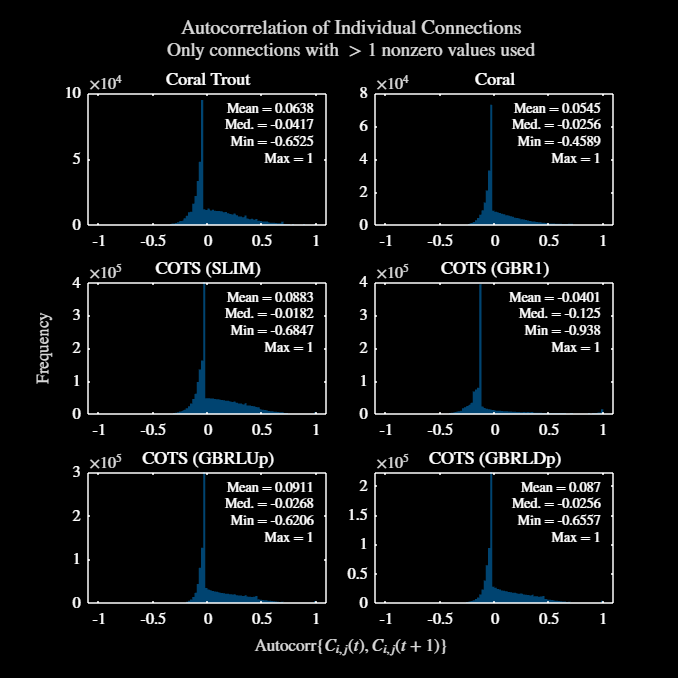

% plot then autocorrelation for everything
figure
plotConnectivityStats({autocorrMonthlyCT, autocorrMonthlyHawaii, ...
    autocorrWeeklySLIM, autocorrWeeklyGBR1, autocorrWeeklyGBRLUp, ...
    autocorrWeeklyGBRLDp}, "autocorrelation", conAnalysisColNames2);
setFontSize(13)
figResize(1.6, 1.2)
lightFig()
saveFig("connectivityAutocorr")
darkFig()
saveFig("connectivityAutocorrDM")

% need to also redo the coefficients of variation for settlement
% probabilities

% next, look at the CV values for each area
[meanConnCT, stdConnCT, ~, ~] = connectivityAnalysisReef( ...
    areaStructGBR.conMats, eps);
[meanConnCTCape, stdConnCTCape, ~, ~] ...
    = connectivityAnalysisReef(areaStructCape.conMats, eps);
[meanConnCTNorth, stdConnCTNorth, ~, ~] ...
    = connectivityAnalysisReef(areaStructNorth.conMats, eps);
[meanConnCTCairns, stdConnCTCairns, ~, ~] ...
    = connectivityAnalysisReef(areaStructCairns.conMats, eps);
[meanConnCTTowns, stdConnCTTowns, ~, ~] ...
    = connectivityAnalysisReef(areaStructTowns.conMats, eps);
[meanConnCTSwains, stdConnCTSwains, ~, ~] ...
    = connectivityAnalysisReef(areaStructSwains.conMats, eps);

figure
plotConnectivityStats({stdConnCT ./ meanConnCT, stdConnCTCape ...
    ./ meanConnCTCape, stdConnCTNorth ./ meanConnCTNorth, ...
    stdConnCTCairns ./ meanConnCTCairns, stdConnCTTowns ...
    ./ meanConnCTTowns, stdConnCTSwains ./ meanConnCTSwains}, ...
    "CVLoc", ["Whole GBR", "Cape Region", "Northern GBR Region", ...
    "Cairns Region", "Townsville Region", "Swains Region"])

ans =   1×6 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes


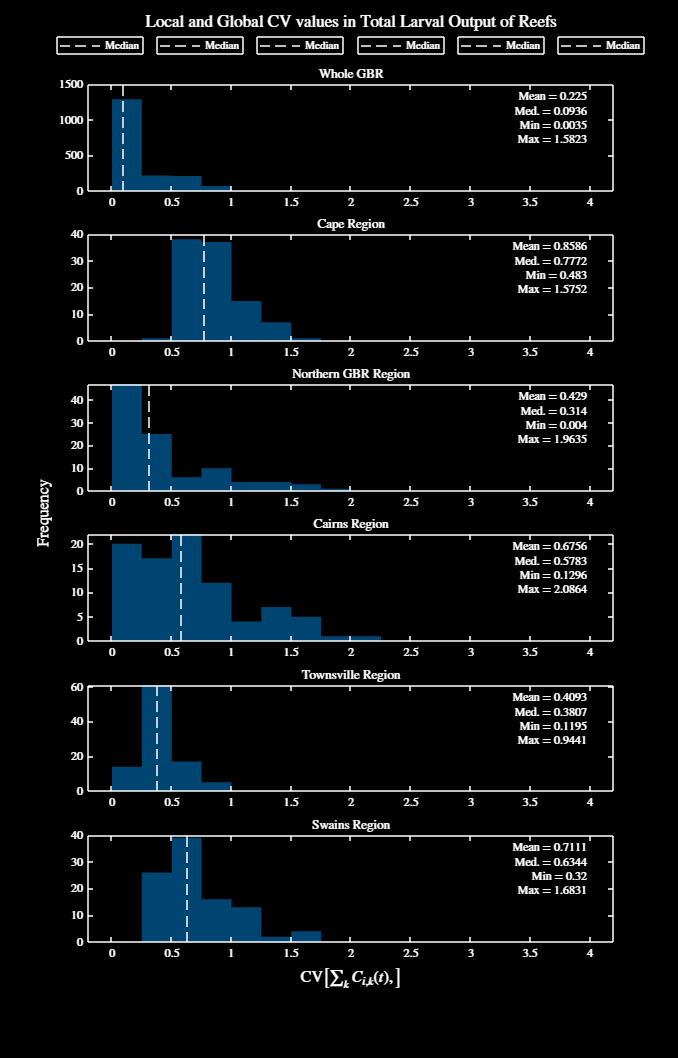

figResize(2.5, 1.2)
lightFig()
saveFig("settlementCVs")
darkFig()
saveFig("settlementCVsDM")

% in hindsight, the above is a little dumb, and I should instead do a
% figure here for all of the biophysical models - first going to redo the
% old one doe

% calculate all the means and sds
[meanConnCT, stdConnCT, minMaxConnCT, ~] = connectivityAnalysis( ...
    conMatsCT, eps);
[meanConnSLIM, stdConnSLIM, minMaxConnSLIM, ~] = ...
    connectivityAnalysis(conMatsSLIM, eps);
[meanConnGBR1, stdConnGBR1, minMaxConnGBR1, ~] = connectivityAnalysis( ...
    conMatsGBR1, eps);
[meanConnGBRLUp, stdConnGBRLUp, minMaxConnGBRLUp, ~] = ...
    connectivityAnalysis(conMatsGBRLUp, eps);
[meanConnGBRLDp, stdConnGBRLDp, minMaxConnGBRLDp, ~] = connectivityAnalysis( ...
    conMatsGBRLDp, eps);
[meanConnHaw, stdConnHaw, minMaxConnHaw, ~] = connectivityAnalysis( ...
    conMatsHawaii, eps);

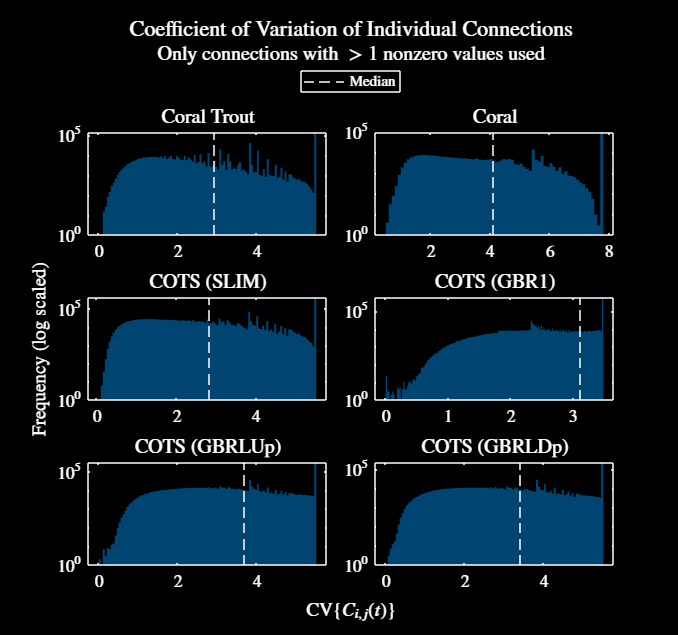

figure
plotConnectivityStats({stdConnCT ./ meanConnCT, stdConnHaw ./ meanConnHaw, ...
    stdConnSLIM ./ meanConnSLIM, stdConnGBR1 ./ meanConnGBR1, ...
    stdConnGBRLUp ./ meanConnGBRLUp, stdConnGBRLDp ./ meanConnGBRLDp}, ...
    "CV", conAnalysisColNames2);
setFontSize(14)
figResize(1.5, 1.2)
lightFig()
saveFig("connectivityCVs")
darkFig()
saveFig("connectivityCVsDM")

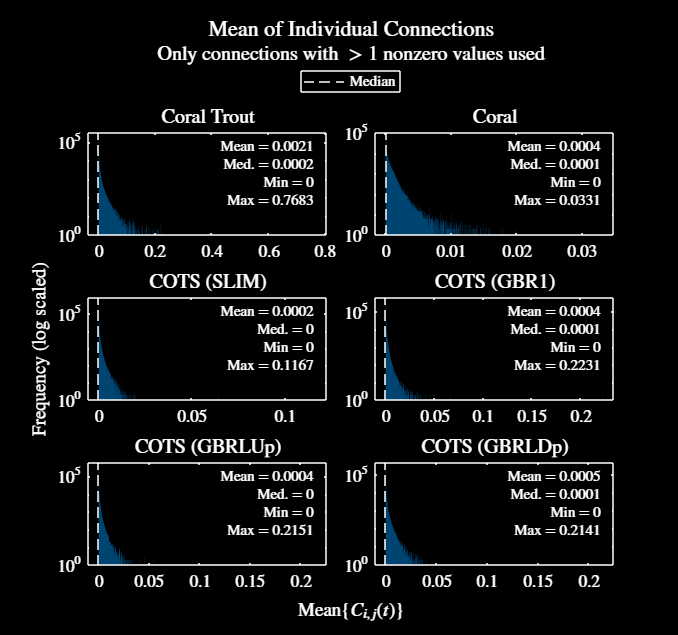

% also go and redo the means and standards etc
figure
plotConnectivityStats({meanConnCT, meanConnHaw, meanConnSLIM, ...
    meanConnGBR1, meanConnGBRLUp, meanConnGBRLDp}, "mean", ...
    conAnalysisColNames2);
setFontSize(14)
figResize(1.5, 1.2)
lightFig()
saveFig("connectivityMeans")
darkFig()
saveFig("connectivityMeansDM")

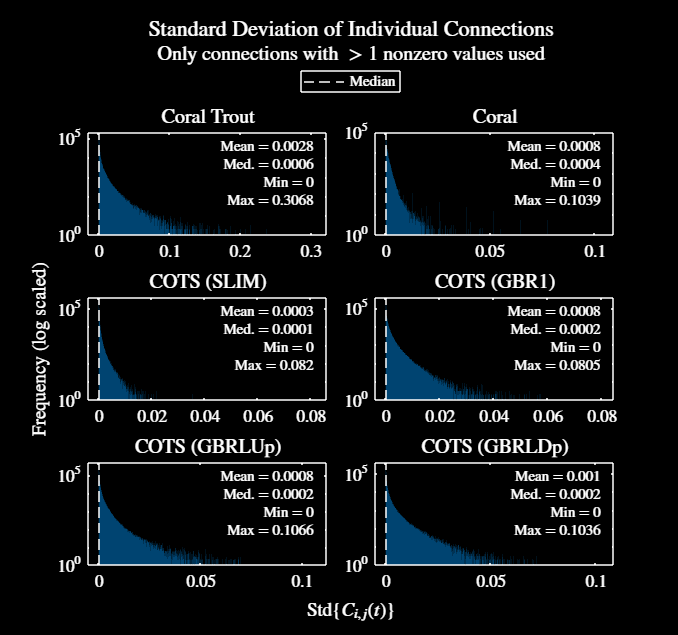

figure
plotConnectivityStats({stdConnCT, stdConnHaw, stdConnSLIM, stdConnGBR1, ...
    stdConnGBRLUp, stdConnGBRLDp}, "std", conAnalysisColNames2);
setFontSize(14)
figResize(1.5, 1.2)
lightFig()
saveFig("connectivityStds")
darkFig()
saveFig("connectivityStdsDM")

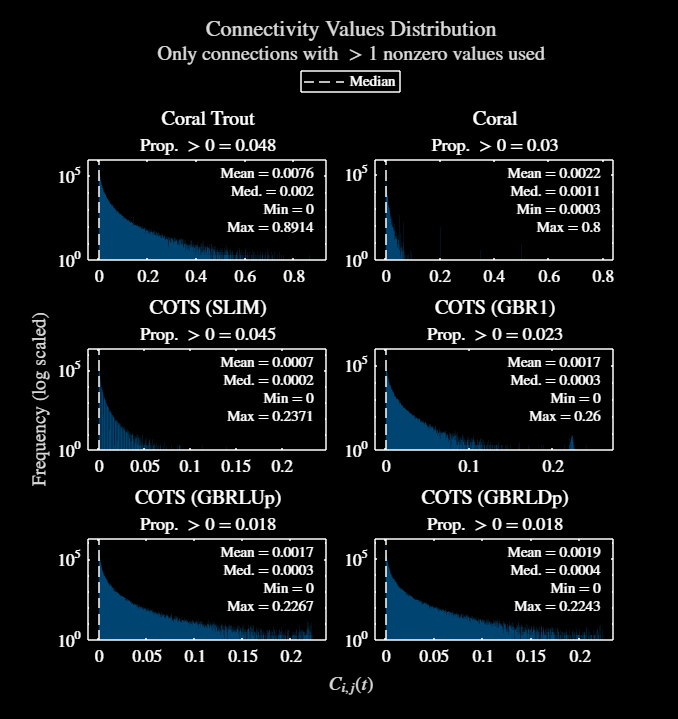

% also just redo the distributions
figure
plotConnectivityDist({conMatsCT, conMatsHawaii, conMatsSLIM, ...
    conMatsGBR1, conMatsGBRLUp, conMatsGBRLDp}, conAnalysisColNames2)
setFontSize(14)
figResize(1.7, 1.2)
lightFig()
saveFig("connectivityDistribution")
darkFig()
saveFig("connectivityDistributionDM")

clear meanConnCT stdConnCT minMaxConnCT meanConnSLIM stdConnSLIM ...
    minMaxConnSLIM meanConnGBRLUp stdConnGBRLUp minMaxConnGBRLUp ...
    meanConnGBR1 stdConnGBR1 minMaxConnGBR1 meanConnGBRLDp ...
    stdConnGBRLDp minMaxConnGBRLDp

% now do the same, but for the settlement probabilities
[meanSettCT, stdSettCT, minMaxConnCT, ~] = connectivityAnalysisReef( ...
    conMatsCT, eps);
[meanSettSLIM, stdSettSLIM, minMaxConnSLIM, ~] = ...
    connectivityAnalysisReef(conMatsSLIM, eps);
[meanSettGBRLUp, stdSettGBRLUp, minMaxConnGBRLUp, ~] = ...
    connectivityAnalysisReef(conMatsGBRLUp, eps);
[meanSettGBR1, stdSettGBR1, minMaxConnGBR1, ~] = connectivityAnalysisReef( ...
    conMatsGBR1, eps);
[meanSettGBRLDp, stdSettGBRLDp, minMaxConnGBRLDp, ~] = connectivityAnalysisReef( ...
    conMatsGBRLDp, eps);
[meanSettHaw, stdSettHaw, minMaxConnHaw, ~] = connectivityAnalysisReef( ...
    conMatsHawaii, eps);

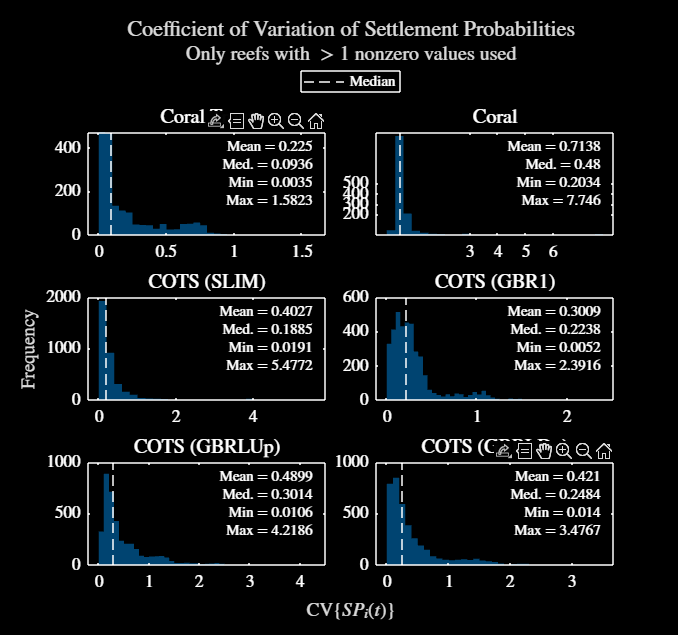

figure
plotConnectivityStats({stdSettCT ./ meanSettCT, stdSettHaw ./ meanSettHaw, ...
    stdSettSLIM ./ meanSettSLIM, stdSettGBR1 ./ meanSettGBR1, ...
    stdSettGBRLUp ./ meanSettGBRLUp, stdSettGBRLDp ./ meanSettGBRLDp}, ...
    "CVSett", conAnalysisColNames2);
setFontSize(14)
figResize(1.5, 1.2)
lightFig()
saveFig("settlementCVs")
darkFig()
saveFig("settlementCVsDM")

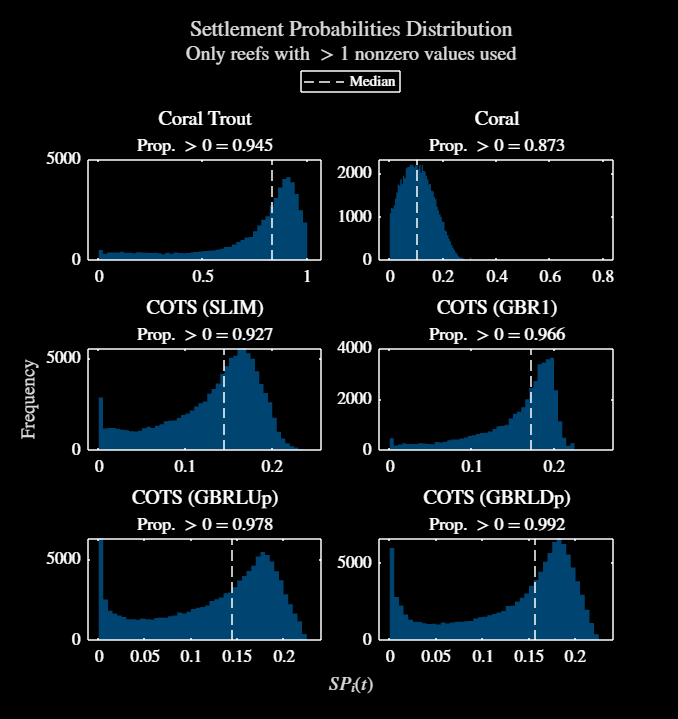

% need to plot the mean and standard deviation of the settlement
% probabilities
% let's also plot the distribution of the connectivity values (nonzero
% only)
figure
plotConnectivityDist({conMatsCT, conMatsHawaii, conMatsSLIM, ...
    conMatsGBR1, conMatsGBRLUp, conMatsGBRLDp}, conAnalysisColNames2, ...
    [], "settlement")
setFontSize(14)
figResize(1.7, 1.2)
lightFig()
saveFig("settlementDistribution")
darkFig()
saveFig("settlementDistributionDM")

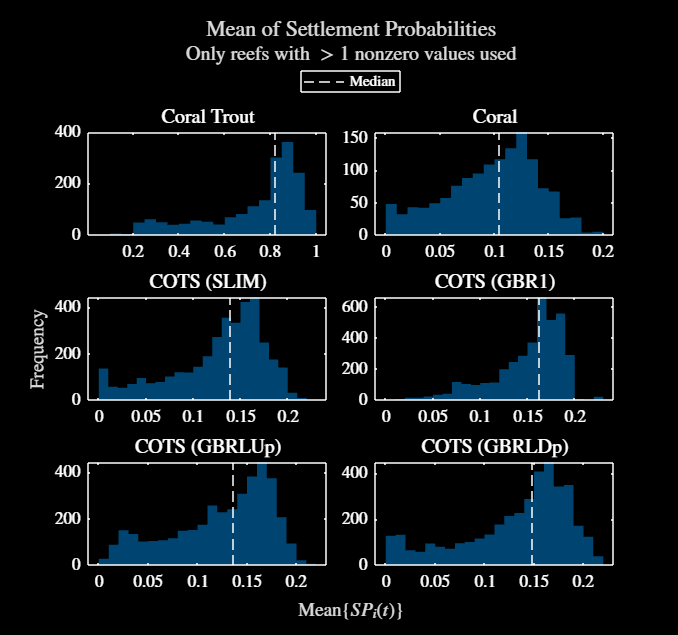

% plot the settlement means
figure
plotConnectivityStats({meanSettCT, meanSettHaw, meanSettSLIM, meanSettGBR1, ...
    meanSettGBRLUp, meanSettGBRLDp}, "meanSett", conAnalysisColNames2);
setFontSize(14)
figResize(1.5, 1.2)
lightFig()
saveFig("settlementMeans")
darkFig()
saveFig("settlementMeansDM")

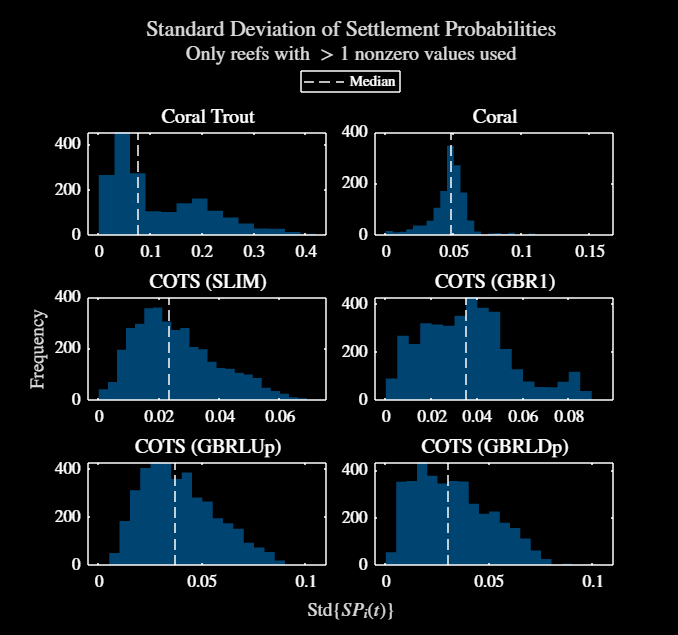

% plot the settlement standard deviations
figure
plotConnectivityStats({stdSettCT, stdSettHaw, stdSettSLIM, stdSettGBR1, ...
    stdSettGBRLUp, stdSettGBRLDp}, "stdSett", conAnalysisColNames2);
setFontSize(14)
figResize(1.5, 1.2)
lightFig()
saveFig("settlementStds")
darkFig()
saveFig("settlementStdsDM")

clear meanSett* stdSett*

## Analytical System Figure Redo

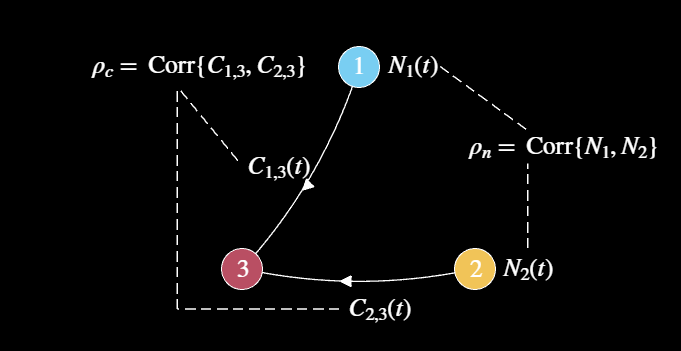

% so that I have a nice little visual for the report, I will do something
% similar to the above, but for three reefs - and remove the colorbar
% methinks
var1 = [0, 0, 0.1; 0, 0, 0.1; 0, 0, 0];
figure
hold on
plot(0, -1.1, 'k.')
plot(0, -1.1, 'w.')
visualiseConMat(var1, [], "hehe")
text(-0.85, 0.25, "$C_{1, 3}(t)$")
text(-0.1, -0.8, "$C_{2, 3}(t)$")
text(-2, 1, "$\rho_c = \,$ Corr$ \{ C_{1, 3}, \, C_{2, 3} \}$")
plot([-0.9, -1.35], [0.3, 0.85], 'k--')
plot([-1.35, -1.35], [-0.8, 0.85], 'k--')
plot([-0.15, -1.35], [-0.8, -0.8], 'k--')
text(0.2, 1, "$N_1(t)$")
text(1.05, -0.5, "$N_2(t)$")
text(0.8, 0.4, "$\rho_n = \,$ Corr$\{ N_1, \, N_2 \}$")
plot([0.6, 1.25], [1, 0.525], 'k--')
plot([1.25, 1.25], [-0.35, 0.28], 'k--')

figResize(1.1, 1.6)
setFontSize(23)
lightFig()
saveFig("threeReefAnalytical")
darkFig()
saveFig("threeReefAnalyticalDM")

specStructCT.successVec

ans =     0.6000    0.7000    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900


actionStructFin.actionEffect

ans =     0.6800    0.8300    0.9500    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700


sum(cumprod(specStructCT.successVec))

ans = 2.4818

sum(cumprod(actionStructFin.actionEffect)) 

ans = 6.3327

sum(cumprod(actionStructFin.actionEffect)) ...
    / sum(cumprod(specStructCT.successVec))

ans = 2.5516


sum(cumprod(actionStruct.actionEffect)) 

ans = 6.3327

sum(cumprod(actionStruct.actionEffect)) ...
    / sum(cumprod(specStructCT.successVec))

ans = 2.5516

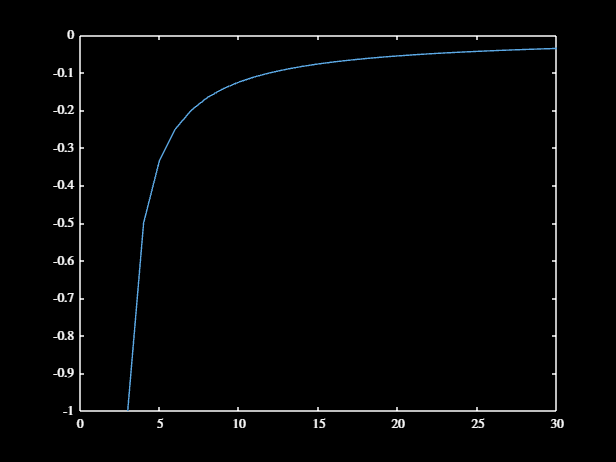

% testing some bs
var3 = 3:30;
var4 = zeros(size(var3));
for i = 1:length(var3)
    n = var3(i);
    var1 = zeros(n, 1);
    var1(2) = 1;
    var4(i) = corr(var1(1:(end - 1)), var1(2:end));
end
figure
plot(var3, var4)
darkFig()

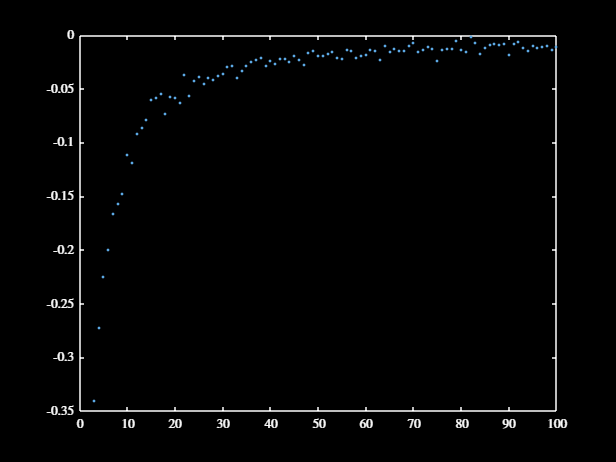

var3 = 3:100;
var5 = 1000;
var4 = zeros(length(var3), var5);
for i = 1:length(var3)
    n = var3(i);
    for j = 1:var5
        var1 = rand(n, 1);
        var4(i, j) = corr(var1(1:(end - 1)), var1(2:end));
    end
end
figure
plot(var3, mean(var4, 2), '.')

darkFig()

## Recalculating the Tables of Results

summaryTable = calcMPASummary(simOutCellCape, "Cape");
summaryTable(2, :) = calcMPASummary(simOutCellNorth, "North");
summaryTable(3, :) = calcMPASummary(simOutCellCairns, "Cairns");
summaryTable(4, :) = calcMPASummary(simOutCellTowns, "Townsville");
summaryTable(5, :) = calcMPASummary(simOutCellSwains, "Swains");
summaryTable{6, :} = ["Average", mean(summaryTable{1:5, 2:end}, 1)];
summaryTable

summaryTable = 6×15 table
     studyArea      varRedLCVsB    varRedLCVsR    varRedBVsR    expValDecLCVsR    expValDecBVsR    expValIncBVsLC    expValIncLCVsR    expValIncBVsR    expValIncFBVsB    expValIncNVsR    varIncLCVsR    varIncBVsR    SlopeLC    SlopeB
    ____________    ___________    ___________    __________    ______________    _____________    ______________    ______________    _____________    ______________    _____________    ___________    __________    _______    ______

summaryTable2 = calcMPASummary(simOutCellCape, "Cape", "sys");
summaryTable2(2, :) = calcMPASummary(simOutCellNorth, "North", "sys");
summaryTable2(3, :) = calcMPASummary(simOutCellCairns, "Cairns", "sys");
summaryTable2(4, :) = calcMPASummary(simOutCellTowns, "Townsville", "sys");
summaryTable2(5, :) = calcMPASummary(simOutCellSwains, "Swains", "sys");
summaryTable2{6, :} = ["Average", mean(summaryTable2{1:5, 2:end}, 1)];
summaryTable2

summaryTable2 = 6×15 table
     studyArea      varRedLCVsB    varRedLCVsR    varRedBVsR    expValDecLCVsR    expValDecBVsR    expValIncBVsLC    expValIncLCVsR    expValIncBVsR    expValIncFBVsB    expValIncNVsR    varIncLCVsR    varIncBVsR    SlopeLC    SlopeB
    ____________    ___________    ___________    __________    ______________    _____________    ______________    ______________    _____________    ______________    _____________    ___________    __________    _______    ______

summaryTable(:, "expValIncBVsR") - summaryTable2(:, "expValIncBVsR")

ans = 6×1 table
    expValIncBVsR
    _____________

               0 
               0 
     -1.1857e-05 
               0 
               0 
               0 


abs(summaryTable(:, 2:end) - summaryTable2(:, 2:end))

ans = 6×14 table
    varRedLCVsB    varRedLCVsR    varRedBVsR    expValDecLCVsR    expValDecBVsR    expValIncBVsLC    expValIncLCVsR    expValIncBVsR    expValIncFBVsB    expValIncNVsR    varIncLCVsR    varIncBVsR     SlopeLC     SlopeB 
    ___________    ___________    __________    ______________    _____________    ______________    ______________    _____________    ______________    _____________    ___________    __________    _________    _______

     0.0029666     0.00031637      0.0040448      9.1279e-05    

simOutCellCape{end}.methodStruct.methodInd

ans = "MPTLarvContSys"